val = bin_to_float('00111111000010100101000010100011');
class(val)

ans = 'double'

fprintf("%.20f\n", val);

0.54029291868209838867





fx_addv = sfi(128, 8 + 24, 24)

fx_addv =   128.0000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 32
        FractionLength: 24

fx_cos = sfi(fx_addv, 2, 16)

fx_cos =    1.5259e-05

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 2
        FractionLength: 16

fx_cos2 = sfi(128, 2, 16)

fx_cos2 =    1.5259e-05

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 2
        FractionLength: 16



INT_LEN = 2;
FRAC_LEN = 20;
CORDIC_ITERS = 16;
v = 0

v = 0

a = custom_cordic(INT_LEN, FRAC_LEN, CORDIC_ITERS, v)

a =     1.0000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 22
        FractionLength: 20

fprintf("%.20f\n",a)

1.00000095367431640625


float_to_bin(a)

ans = '00111111100000000000000000001000'


num2hex(single(0.5))

ans = '3f000000'

46 / 50 * 140 

ans = 128.8000


a = single(128.0000152587890625);
b = single(127.99999237060546875);
fprintf("%.20f\n",a);

128.00001525878906250000


fprintf("%.20f\n",b);

127.99999237060546875000


da = a - 128;
db = b - 128;
fprintf("%.20f\n", da);     % 0x37800000

0.00001525878906250000


fprintf("%.20f\n", db);     % 0xb7000000

-0.00000762939453125000



xda = ufi(da, 21, 20)

xda =    1.5259e-05

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 21
        FractionLength: 20

xda.bin

ans = '000000000000000010000'


INT_LEN = 2;
FRAC_LEN = 20;
CORDIC_ITERS = 16;
cda = custom_cordic(INT_LEN, FRAC_LEN, CORDIC_ITERS, da);

cda =      1

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 19

cdb = custom_cordic(INT_LEN, FRAC_LEN, CORDIC_ITERS, db);

cdb =     1.0000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 21
        FractionLength: 19

fprintf("%.25f\n", cda);     % 0x3f800008

1.0000000000000000000000000


fprintf("%.25f\n", cdb);     % 0x3f800028

1.0000076293945312500000000


% -------------------------------------------------------
% For checking cordic.v outputs
% -------------------------------------------------------

INT_LEN = 2;
FRAC_LEN = 31;
CORDIC_ITERS = 16;
in_dbl = [0.0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1.0];
in_flt = single(in_dbl);
% result = custom_instr_model(INT_LEN, FRAC_LEN, CORDIC_ITERS, in_flt);
% ref = 0.5 * in_dbl + in_dbl ^ 2 * cos((in_dbl - 128) / 128);
result = custom_cordic(INT_LEN, FRAC_LEN, CORDIC_ITERS, in_flt);
ref = cos(in_dbl);

% fprintf("INPUTS");
% for v = in_dbl
%     fprintf("%.20f \t %s\n", single(v), );
% end

fprintf("CORDIC FRAC: %d, ITERS: %d", FRAC_LEN, CORDIC_ITERS);

CORDIC FRAC: 31, ITERS: 16

for v = result
    fprintf("%.20f \t %s\n", v, v.bin);
end

0.99999999906867742538 	 001111111111111111111111111111110
0.99500490911304950714 	 001111111010111000101001000100100
0.98006533179432153702 	 001111101011100101100011111100010
0.95533562032505869865 	 001111010010010000111000000000111
0.92106238473206758499 	 001110101111001010101111101001010
0.87757753254845738411 	 001110000010101000111010111101001
0.82532518357038497925 	 001101001101001000100000101110000
0.76483105029910802841 	 001100001111001011111101111011110
0.69670751970261335373 	 001011001001011011011011001000110
0.62161196907982230186 	 001001111100100001111101100100011
0.54029291961342096329 	 001000101001010000101000110000010



fprintf("Reference");

Reference

for v = ref
    fprintf("%.20f \n", v);
end

1.00000000000000000000 
0.99500416527802570954 
0.98006657784124162625 
0.95533648912560598099 
0.92106099400288510282 
0.87758256189037275874 
0.82533561490967832786 
0.76484218728448849500 
0.69670670934716538714 
0.62160996827066439252 
0.54030230586813976501 



% fprintf("Custom: %.20f", result)
% fprintf("Golden: %.20f", ref)



% -------------------------------------------------------
% Validating CORDIC block implementation
% -------------------------------------------------------

INT_LEN = 2;
FRAC_LEN = 20;
CORDIC_ITERS = 16;
in_dbl = [0.0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1.0];
in_flt = single(in_dbl);

fprintf("CORDIC FRAC: %d, ITERS: %d", FRAC_LEN, CORDIC_ITERS);

CORDIC FRAC: 20, ITERS: 16

fprintf("Input \t ref_out \t CORDIC_out \n")

Input 	 ref_out 	 CORDIC_out 


for v = in_flt
    ref = cos(v);
    out = custom_cordic(INT_LEN, FRAC_LEN, CORDIC_ITERS, v);
    % fprintf("%.20f \t %s \t %.20f \t %.20f \n", v, float_to_bin(v), ref, out);
    fprintf("inputs[%d] = 32'b%s; \t // in: %.1f \t out: %.20f \n", v * 10, float_to_bin(v), v, out);
end

inputs[0] = 32'b00000000000000000000000000000000; 	 // in: 0.0 	 out: 1.00000095367431640625 
inputs[1] = 32'b00111101110011001100110011001101; 	 // in: 0.1 	 out: 0.99500274658203125000 
inputs[2] = 32'b00111110010011001100110011001101; 	 // in: 0.2 	 out: 0.98006725311279296875 
inputs[3] = 32'b00111110100110011001100110011010; 	 // in: 0.3 	 out: 0.95533657073974609375 
inputs[4] = 32'b00111110110011001100110011001101; 	 // in: 0.4 	 out: 0.92105865478515625000 
inputs[5] = 32'b00111111000000000000000000000000; 	 // in: 0.5 	 out: 0.87757778167724609375 
inputs[6] = 32'b00111111000110011001100110011010; 	 // in: 0.6 	 out: 0.82532501220703125000 
inputs[7] = 32'b00111111001100110011001100110011; 	 // in: 0.7 	 out: 0.76482963562011718750 
inputs[8] = 32'b00111111010011001100110011001101; 	 // in: 0.8 	 out: 0.69670677185058593750 
inputs[9] = 32'b00111111011001100110011001100110; 	 // in: 0.9 	 out: 0.62161064147949218750 
inputs[10] = 32'b00111111100000000000000000000000; 	 // in: 


gold = cos(in_dbl);
cordic_result = custom_cordic(INT_LEN, FRAC_LEN, CORDIC_ITERS, in_flt);

% -------------------------------------------------------
% Generate CORDIC inputs
% -------------------------------------------------------
n_samples = 5000;
inputs_dbl = -1 + (2).*rand(n_samples,1); %   [-1, 1]
inputs_flt = single(inputs_dbl)

inputs_flt = 5000×1 single column vector
    0.3523
   -0.2331
    0.7434
   -0.6442
   -0.7890
   -0.7092
   -0.3435
    0.6323
    0.3209
   -0.5258



fileID = fopen("test/input/inputs.txt","w")

fileID = 5


for v = inputs_flt
    fprintf(fileID, "%s\n", string(num2hex(v)));
end

fclose(fileID);

fi("111111111110010011000",21,20)

Error using embedded.fi/fifactory
Invalid parameter/value pair arguments.

Error in fi (line 226)
a = embedded.fi(varargin{:});

% -------------------------------------------------------
% Evaluate CORDIC ouptut error from file
% -------------------------------------------------------

flt_inputs = read_hex_single_file("test/input/inputs.txt");

SZ = 5000


flt_outputs = read_hex_single_file("test/output/outputs1.txt");

SZ = 5000


dbl_inputs = double(flt_inputs);
ref_outputs = cos(dbl_inputs);
errors = ref_outputs - double(flt_outputs);
sq_error = errors .^ 2;
mse = sum(sq_error) / n_samples

mse = 8.8362e-11

ci_upper = mse + norminv(0.95) * std(sq_error) / sqrt(n_samples)

ci_upper = 9.1274e-11


flt_outputs = read_hex_single_file("test/output/outputs2.txt");

SZ = 5000


dbl_inputs = double(flt_inputs);
ref_outputs = cos(dbl_inputs);
errors = ref_outputs - double(flt_outputs);
sq_error = errors .^ 2;
mse = sum(sq_error) / n_samples

mse = 8.7176e-11

ci_upper = mse + norminv(0.95) * std(sq_error) / sqrt(n_samples)

ci_upper = 9.0056e-11

% -------------------------------------------------------
% Generate angles
% -------------------------------------------------------

indices = 0:1:15

indices =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


tan_alpha = 2 .^ (-indices)

tan_alpha =     1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001    0.0001    0.0000


alpha = atan(tan_alpha)

alpha =     0.7854    0.4636    0.2450    0.1244    0.0624    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001    0.0001    0.0000


bin_alpha = ufi(alpha, 21, 20)

bin_alpha =     0.7854    0.4636    0.2450    0.1244    0.0624    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001    0.0001    0.0000

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 21
        FractionLength: 20

% bin_alpha.bin
% halpha = bin_alpha.hex
% halpha(:,1)
bin_alpha(1)

ans =     0.7854

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 21
        FractionLength: 20

for i = 1:length(bin_alpha)
    x = bin_alpha(i);
    fprintf("cordic_operation #(.rotate_index(4'd%d), .rotate_angle(21'h%s)) rotation%d ( x%d, y%d, z%d, x%d_out, y%d_out, z%d_out); \n", i-1, x.hex, i-1, i-1, i-1, i-1, i-1, i-1, i-1);
end

cordic_operation #(.rotate_index(4'd0), .rotate_angle(21'h0c90fe)) rotation0 ( x0, y0, z0, x0_out, y0_out, z0_out); 
cordic_operation #(.rotate_index(4'd1), .rotate_angle(21'h076b1a)) rotation1 ( x1, y1, z1, x1_out, y1_out, z1_out); 
cordic_operation #(.rotate_index(4'd2), .rotate_angle(21'h03eb6f)) rotation2 ( x2, y2, z2, x2_out, y2_out, z2_out); 
cordic_operation #(.rotate_index(4'd3), .rotate_angle(21'h01fd5c)) rotation3 ( x3, y3, z3, x3_out, y3_out, z3_out); 
cordic_operation #(.rotate_index(4'd4), .rotate_angle(21'h00ffab)) rotation4 ( x4, y4, z4, x4_out, y4_out, z4_out); 
cordic_operation #(.rotate_index(4'd5), .rotate_angle(21'h007ff5)) rotation5 ( x5, y5, z5, x5_out, y5_out, z5_out); 
cordic_operation #(.rotate_index(4'd6), .rotate_angle(21'h003fff)) rotation6 ( x6, y6, z6, x6_out, y6_out, z6_out); 
cordic_operation #(.rotate_index(4'd7), .rotate_angle(21'h002000)) rotation7 ( x7, y7, z7, x7_out, y7_out, z7_out); 
cordic_operation #(.rotate_index(4'd8), .rotate_angle(21'h001000

% -------------------------------------------------------
% Generate verilog testbench
% -------------------------------------------------------

inputs = single(0:20:255)

inputs = 1×13 single row vector
     0    20    40    60    80   100   120   140   160   180   200   220   240


in_flt = float_to_bin(inputs)

in_flt = 13×32 char array
    '00000000000000000000000000000000'
    '01000001101000000000000000000000'
    '01000010001000000000000000000000'
    '01000010011100000000000000000000'
    '01000010101000000000000000000000'
    '01000010110010000000000000000000'
    '01000010111100000000000000000000'
    '01000011000011000000000000000000'
    '01000011001000000000000000000000'
    '01000011001101000000000000000000'
    '01000011010010000000000000000000'
    '01000011010111000000000000000000'
    '01000011011100000000000000000000'


half = inputs ./ 2

half = 1×13 single row vector
     0    10    20    30    40    50    60    70    80    90   100   110   120


div128 = inputs ./ 128

div128 = 1×13 single row vector
         0    0.1562    0.3125    0.4688    0.6250    0.7812    0.9375    1.0938    1.2500    1.4062    1.5625    1.7188    1.8750



fprintf("reg [31:0] inputs [13]; \n")

reg [31:0] inputs [13]; 


for i = uint16(1:(length(inputs)))
    fprintf("inputs[%d] = 32'b%s;\n", i-1, float_to_bin(inputs(i)) );
end

inputs[0] = 32'b00000000000000000000000000000000;
inputs[1] = 32'b01000001101000000000000000000000;
inputs[2] = 32'b01000010001000000000000000000000;
inputs[3] = 32'b01000010011100000000000000000000;
inputs[4] = 32'b01000010101000000000000000000000;
inputs[5] = 32'b01000010110010000000000000000000;
inputs[6] = 32'b01000010111100000000000000000000;
inputs[7] = 32'b01000011000011000000000000000000;
inputs[8] = 32'b01000011001000000000000000000000;
inputs[9] = 32'b01000011001101000000000000000000;
inputs[10] = 32'b01000011010010000000000000000000;
inputs[11] = 32'b01000011010111000000000000000000;
inputs[12] = 32'b01000011011100000000000000000000;



fprintf("reg [31:0] half [13]; \n")

reg [31:0] half [13]; 


for i = uint16(1:(length(inputs)))
    fprintf("half[%d] = 32'b%s;\n", i-1, float_to_bin(half(i)) );
end

half[0] = 32'b00000000000000000000000000000000;
half[1] = 32'b01000001001000000000000000000000;
half[2] = 32'b01000001101000000000000000000000;
half[3] = 32'b01000001111100000000000000000000;
half[4] = 32'b01000010001000000000000000000000;
half[5] = 32'b01000010010010000000000000000000;
half[6] = 32'b01000010011100000000000000000000;
half[7] = 32'b01000010100011000000000000000000;
half[8] = 32'b01000010101000000000000000000000;
half[9] = 32'b01000010101101000000000000000000;
half[10] = 32'b01000010110010000000000000000000;
half[11] = 32'b01000010110111000000000000000000;
half[12] = 32'b01000010111100000000000000000000;



fprintf("reg [31:0] div128 [13]; \n")

reg [31:0] div128 [13]; 


for i = uint16(1:(length(inputs)))
    fprintf("div128[%d] = 32'b%s;\n", i-1, float_to_bin(div128(i)) );
end

div128[0] = 32'b00000000000000000000000000000000;
div128[1] = 32'b00111110001000000000000000000000;
div128[2] = 32'b00111110101000000000000000000000;
div128[3] = 32'b00111110111100000000000000000000;
div128[4] = 32'b00111111001000000000000000000000;
div128[5] = 32'b00111111010010000000000000000000;
div128[6] = 32'b00111111011100000000000000000000;
div128[7] = 32'b00111111100011000000000000000000;
div128[8] = 32'b00111111101000000000000000000000;
div128[9] = 32'b00111111101101000000000000000000;
div128[10] = 32'b00111111110010000000000000000000;
div128[11] = 32'b00111111110111000000000000000000;
div128[12] = 32'b00111111111100000000000000000000;


% -------------------------------------------------------
% Generate inner function testbench
% -------------------------------------------------------

INT_LEN = 2;
FRAC_LEN = 20;
CORDIC_ITERS = 16;

inputs = [single(0:25.1:255) 255];
% outputs = custom_instr_cordic(INT_LEN, FRAC_LEN, CORDIC_ITERS, inputs)
% outputs = custom_instr_cordic_dbg(inputs)

% outputs = sfi(inputs, 22, 13);
outputs = ufi(abs((inputs - 128) ./ 128), 21, 20)

outputs =     1.0000    0.8039    0.6078    0.4117    0.2156    0.0195    0.1766    0.3727    0.5688    0.7648    0.9609    0.9922

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Unsigned
            WordLength: 21
        FractionLength: 20

ref_outputs = custom_instr_cosf(inputs)

ref_outputs = 1×12 single row vector
1.0e+04 *

         0    0.0450    0.2094    0.5234    0.9897    1.5810    2.2403    2.8839    3.4074    3.6931    3.6209    3.5687



fprintf("reg [31:0] inputs [%d:0]; \n", length(inputs)-1);

reg [31:0] inputs [11:0]; 


for i = 1:(length(inputs))
    fprintf("inputs[%d] = 32'h%s; //%f \n", i-1, num2hex(inputs(i)), inputs(i));
end

inputs[0] = 32'h00000000; //0.000000 
inputs[1] = 32'h41c8cccd; //25.100000 
inputs[2] = 32'h4248cccd; //50.200001 
inputs[3] = 32'h4296999a; //75.300003 
inputs[4] = 32'h42c8cccd; //100.400002 
inputs[5] = 32'h42fb0000; //125.500000 
inputs[6] = 32'h4316999a; //150.600006 
inputs[7] = 32'h432fb333; //175.699997 
inputs[8] = 32'h4348cccd; //200.800003 
inputs[9] = 32'h4361e666; //225.899994 
inputs[10] = 32'h437b0000; //251.000000 
inputs[11] = 32'h437f0000; //255.000000 



fprintf("reg [31:0] outputs [%d:0]; \n", length(outputs)-1);

reg [31:0] outputs [11:0]; 


for i = 1:(length(outputs))
    oo = outputs(i);
    fprintf("outputs[%d] = 32'h%s; //%f \n", i-1, oo.hex, outputs(i));
end

outputs[0] = 32'h100000; //1.000000 
outputs[1] = 32'h0cdccd; //0.803906 
outputs[2] = 32'h09b99a; //0.607813 
outputs[3] = 32'h069666; //0.411718 
outputs[4] = 32'h037333; //0.215625 
outputs[5] = 32'h005000; //0.019531 
outputs[6] = 32'h02d333; //0.176562 
outputs[7] = 32'h05f666; //0.372656 
outputs[8] = 32'h09199a; //0.568750 
outputs[9] = 32'h0c3ccd; //0.764844 
outputs[10] = 32'h0f6000; //0.960938 
outputs[11] = 32'h0fe000; //0.992188 



fprintf("reg [31:0] outputs [%d:0]; \n", length(ref_outputs)-1);

reg [31:0] outputs [11:0]; 


for i = 1:(length(ref_outputs))
    fprintf("outputs[%d] = 32'h%s; //%f \n", i-1, num2hex(ref_outputs(i)), ref_outputs(i));
end

outputs[0] = 32'h00000000; //0.000000 
outputs[1] = 32'h43e0db52; //449.713440 
outputs[2] = 32'h4502dcc8; //2093.798828 
outputs[3] = 32'h45a38f53; //5233.915527 
outputs[4] = 32'h461aa3bb; //9896.932617 
outputs[5] = 32'h467707fc; //15809.996094 
outputs[6] = 32'h46af061d; //22403.056641 
outputs[7] = 32'h46e14efe; //28839.496094 
outputs[8] = 32'h4705198e; //34073.554688 
outputs[9] = 32'h47104332; //36931.195312 
outputs[10] = 32'h470d716f; //36209.433594 
outputs[11] = 32'h470b670e; //35687.054688 


% -------------------------------------------------------
% Testcase 1 2 3
% -------------------------------------------------------

INT_LEN = 2;
FRAC_LEN = 20;
CORDIC_ITERS = 16;

fn = @(x) (custom_instr_cordic(INT_LEN, FRAC_LEN, CORDIC_ITERS, x))

fn = function_handle with value:
    @(x)(custom_instr_cordic(INT_LEN,FRAC_LEN,CORDIC_ITERS,x))



N = 52;
step = 5;
inputs = single((0:(N-1)) * step);
full_fn(fn, inputs)

920414.12500000000000000000

ans = 0


N = 2041;
step = 1/8;
inputs = single((0:(N-1)) * step);
full_fn(fn, inputs)

36123136.00000000000000000000

ans = 0


N = 261121;
step = 1/1024;
inputs = single((0:(N-1)) * step);
full_fn(fn, inputs)

4621529600.00000000000000000000

ans = 0

% -------------------------------------------------------
% Testcase 1 2 3
% -------------------------------------------------------

fn = @(x) (0.5 .* x + (x .^ 2) .* cos((x - 128) ./ 128));

N = 52;
step = 5;
inputs = single((0:(N-1)) * step);
full_fn(fn, inputs)

920413.50000000000000000000

ans = single
9.2041e+05


N = 2041;
step = 1/8;
inputs = single((0:(N-1)) * step);
full_fn(fn, inputs)

36123104.00000000000000000000

ans = single
36123104


N = 261121;
step = 1/1024;
inputs = single((0:(N-1)) * step);

N = 255 * 4096

N = 1044480

inputs = linspace(0, 255, N)

inputs =          0    0.0002    0.0005    0.0007    0.0010    0.0012    0.0015    0.0017    0.0020    0.0022    0.0024    0.0027    0.0029    0.0032    0.0034    0.0037    0.0039    0.0042    0.0044    0.0046    0.0049    0.0051    0.0054    0.0056    0.0059    0.0061    0.0063    0.0066    0.0068    0.0071    0.0073    0.0076    0.0078    0.0081    0.0083    0.0085    0.0088    0.0090    0.0093    0.0095    0.0098    0.0100    0.0103    0.0105    0.0107    0.0110    0.0112    0.0115    0.0117    0.0120


m = full_fn(fn, inputs)

18485884842.36783599853515625000

m = 1.8486e+10

maxmsb = ceil(log2(m))

maxmsb = 35


maxlsb = -20-log2(N)

maxlsb = -39.9944

N = 2041;
step = 1/8;
ref_fn = @(x) (0.5 .* x + (x .^ 2) .* cos((x - 128) ./ 128));

inputs = single((0:(N-1)) * step);
outputs = ref_fn(inputs);

out_max = max(outputs)

out_max = single
3.7146e+04

out_min = min(outputs)

out_min = single
0


maxMSBX = ceil(log2(out_max))

maxMSBX = single
16

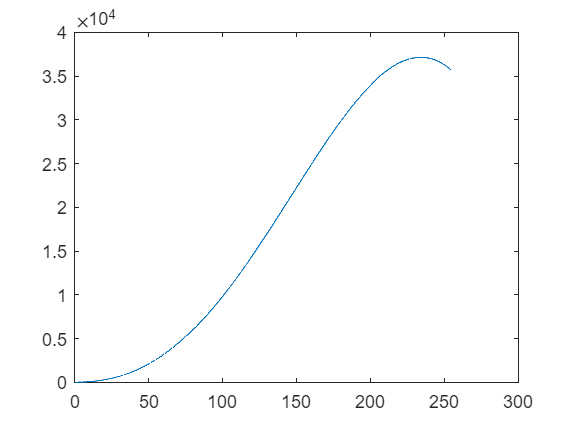


plot(inputs, outputs)

% Define the function to be evaluated
f = @(x) 0.5 .* x + (x .^ 2) .* cos((x - 128) ./ 128);

% Define the input range
x_min = 0;
x_max = 255;

% Evaluate the function over the input range
x = linspace(x_min, x_max, 1000);
y = f(x);

% Find the maximum value and its location
[y_max, i_max] = max(y);
x_max = x(i_max);

% Display the result
fprintf('The maximum value of the function is %f at x = %f.\n', y_max, x_max);

The maximum value of the function is 37146.464657 at x = 234.324324.


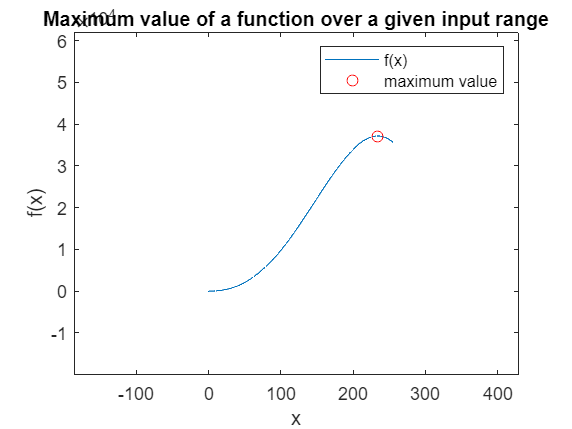


% Plot the function to visualize the result
plot(x, y);
hold on;
plot(x_max, y_max, 'ro');
xlabel('x');
ylabel('f(x)');
title('Maximum value of a function over a given input range');
legend('f(x)', 'maximum value');

maxMSBX = ceil(log2(y_max))

maxMSBX = 16

full_max = 4621531136.00000000000000000000

full_max = 4.6215e+09

ceil(log2(full_max))

ans = 33

% -------------------------------------------------------
% Get the MSE and confidence interval for CORDIC/CUSTOM INSTR config
% -------------------------------------------------------

INT_LEN = 2;
FRAC_LEN = 20;
CORDIC_ITERS = 16;

FXADD_IL = 9;
FXADD_FL = 12;

% custom_fn = @(x) (custom_instr_cordic(INT_LEN, FRAC_LEN, CORDIC_ITERS, x));
% custom_fn = @(x) (custom_instr_cordic_fxadd(INT_LEN, FRAC_LEN, CORDIC_ITERS, FXADD_IL, FXADD_FL, x));
% custom_fn = @(x) (custom_instr_cosf(x)); 
% ref_fn = @(x) (0.5 .* x + (x .^ 2) .* cos((x - 128) ./ 128));

% custom_fn = @(x) (custom_cordic(INT_LEN, FRAC_LEN, CORDIC_ITERS, x));
% ref_fn = @cos;

custom_fn = @(x) sfi((fx_add(FXADD_IL, FXADD_FL, single(x))), INT_LEN+FRAC_LEN, FRAC_LEN);
ref_fn = @(x) sfi(((single(x)-128)./128), INT_LEN+FRAC_LEN, FRAC_LEN);

N_SAMPLES = 10000;
errors = monte_carlo_sim(N_SAMPLES, ref_fn, custom_fn);

result =     0.5708
   -0.9966
   -0.5793
   -0.9114
   -0.1213
   -0.9109
    0.2058
   -0.9617
   -0.6294
   -0.2397
   -0.2026
   -0.5168
   -0.5234
   -0.1519
    0.7661
   -0.2507
    0.3345
   -0.4390
    0.8418
   -0.8196
    0.8835
    0.6741
   -0.2529
   -0.6711
    0.0632
    0.0024
   -0.9995
    0.6709
    0.9626
   -0.7742
    0.6643
   -0.0278
    0.5002
    0.7932
   -0.3704
   -0.8167
   -0.8420
    0.8420
   -0.1665
   -0.9299
    0.3279
   -0.9275
    0.5496
   -0.5413
   -0.3184
   -0.1831
   -0.8572
   -0.0884
   -0.8904
    0.6487
    0.1399
    0.0776
   -0.7329
   -0.7175
   -0.0061
   -0.6599
   -0.1963
   -0.5369
   -0.5144
    0.3376
   -0.5339
    0.6765
   -0.1858
    0.1357
   -0.5483
   -0.4990
    0.1917
    0.7332
   -0.1265
    0.0239
   -0.5754
    0.7754
   -0.4595
    0.4688
   -0.5439
   -0.7649
   -0.0125
   -0.2437
    0.1045
    0.8945
    0.1335
    0.6572
   -0.4517
    0.0300
   -0.6892
   -0.3828
    0.5076
   -0.8716
   -0.5000
    0.1274
 

ref =     0.5709
   -0.9966
   -0.5793
   -0.9114
   -0.1214
   -0.9109
    0.2057
   -0.9617
   -0.6294
   -0.2398
   -0.2027
   -0.5168
   -0.5234
   -0.1518
    0.7660
   -0.2508
    0.3344
   -0.4389
    0.8417
   -0.8195
    0.8835
    0.6742
   -0.2529
   -0.6711
    0.0633
    0.0024
   -0.9995
    0.6709
    0.9625
   -0.7741
    0.6643
   -0.0279
    0.5003
    0.7932
   -0.3704
   -0.8167
   -0.8420
    0.8421
   -0.1665
   -0.9300
    0.3279
   -0.9276
    0.5495
   -0.5413
   -0.3183
   -0.1831
   -0.8571
   -0.0884
   -0.8904
    0.6486
    0.1398
    0.0776
   -0.7328
   -0.7175
   -0.0062
   -0.6599
   -0.1963
   -0.5370
   -0.5144
    0.3375
   -0.5339
    0.6764
   -0.1858
    0.1357
   -0.5484
   -0.4991
    0.1917
    0.7332
   -0.1264
    0.0239
   -0.5755
    0.7753
   -0.4594
    0.4687
   -0.5440
   -0.7649
   -0.0126
   -0.2435
    0.1045
    0.8946
    0.1336
    0.6573
   -0.4517
    0.0300
   -0.6892
   -0.3828
    0.5075
   -0.8715
   -0.5000
    0.1275
    

sq_error = errors.^2;
mse = sum(sq_error) / N_SAMPLES

mse =    5.0968e-09

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 60
        FractionLength: 40

ci_upper = mse + norminv(0.95) * std(sq_error) / sqrt(N_SAMPLES)

ci_upper =    5.1704e-09

          DataTypeMode: Fixed-point: binary point scaling
            Signedness: Signed
            WordLength: 137
        FractionLength: 106

% -------------------------------------------------------
% Explore different configurations
% -------------------------------------------------------

INT_LEN = 2

INT_LEN = 2

FRAC_LENS = [18 19 20]

FRAC_LENS =     18    19    20


N_ITERS = [16 17 18]

N_ITERS =     16    17    18


% FRAC_LENS = [8]
% N_ITERS = [10 15 20]
N_SAMPLES = 2000;

total_configs = length(FRAC_LENS) * length(N_ITERS);

results = zeros(total_configs, 4);
ref_fn = @cos;

i = 1

i = 1

for f_len = FRAC_LENS
    for n_it = N_ITERS
        custom_fn = @(x) (custom_cordic(INT_LEN, f_len, n_it, x));
        errors = monte_carlo_sim(N_SAMPLES, ref_fn, custom_fn);
        sq_error = errors.^2;
        mse = sum(sq_error) / N_SAMPLES;
        ci_upper = mse + norminv(0.95) * std(sq_error) / sqrt(N_SAMPLES);
        results(i,:) = [f_len n_it mse ci_upper];
        i = i + 1
    end
end

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10


results

results =    18.0000   16.0000    0.0000    0.0000
   18.0000   17.0000    0.0000    0.0000
   18.0000   18.0000    0.0000    0.0000
   19.0000   16.0000    0.0000    0.0000
   19.0000   17.0000    0.0000    0.0000
   19.0000   18.0000    0.0000    0.0000
   20.0000   16.0000    0.0000    0.0000
   20.0000   17.0000    0.0000    0.0000
   20.0000   18.0000    0.0000    0.0000


Unrecognized function or variable 'csv'.

implements: y = 0.5*x + x^2*cos((x-128)/128) 

function result = custom_instr_cordic(int_len, frac_len, cordic_iters, in_flt)    
    cos_in_flt = (in_flt-128)./128;
    cos_result = custom_cordic(int_len, frac_len, cordic_iters, cos_in_flt);
    
    result = 0.5 .* in_flt + (in_flt .^ 2) .* single(cos_result);
end

function result = custom_instr_cordic_dbg(in_flt)    
    result = 0.5 .* in_flt + (in_flt .^ 2) .* single(0.5);
end

function result = custom_instr_cordic_fxadd(int_len, frac_len, cordic_iters, add_IL, add_FL, in_flt)    
    add_WL = add_IL + add_FL;
    word_len = int_len + frac_len;

    in_fixed = sfi(in_flt, add_WL, add_FL);
    fxadd_out = (in_fixed-128)./128;
    cos_in = sfi(fxadd_out, word_len, frac_len);

    cos_result = cordiccos(cos_in, cordic_iters);
    
    result = 0.5 .* in_flt + (in_flt .^ 2) .* single(cos_result);
end

function result = custom_instr_cosf(in_flt)    
    cos_in_flt = (in_flt-128)./128;
    cos_result = cos(cos_in_flt);
    
    result = 0.5 .* in_flt + (in_flt .^ 2) .* single(cos_result);
end

function result = custom_cordic(int_len, frac_len, cordic_iters, in_flt)
    word_len = int_len + frac_len;

    cos_in_fix = sfi(in_flt, word_len, frac_len);
    result = cordiccos(cos_in_fix, cordic_iters);
end

function fxadd_out = fx_add(add_IL, add_FL, in_flt)    
    add_WL = add_IL + add_FL;
    in_fixed = sfi(in_flt, add_WL, add_FL);
    fxadd_out = (in_fixed-128)./128;
end

function errors = monte_carlo_sim(n_samples, ref_fn, custom_fn)
    % results = [inputs, custom_outputs, ref_outputs, errors]
    inputs_dbl = 0 + 255.*rand(n_samples,1); %    [0, 255]
    % inputs_dbl = rand(n_samples,1);               [0, 1]
    % inputs_dbl = -1 + (2).*rand(n_samples,1); %   [-1, 1]
    inputs_flt = single(inputs_dbl); 

    result = custom_fn(inputs_flt) % custom_cordic (fp32 -> fx)
    ref = ref_fn(inputs_dbl) % cos

    errors = double(result) - ref;

    % disp(result)
    % disp(ref)
    % disp(errors)
end

function result = full_fn(inner_fn, x)
    % x = single((0:51) * (5));

    % ref_fn = @(x) (0.5 .* x + (x .^ 2) .* cos((x - 128) ./ 128));
    fx = inner_fn(x);

    res = 0;
    for val = fx  
        res = res + val;
    end

    fprintf("%.20f", res)
    result = res;
end

function val = bin_to_float(S)
    % S = '10101110101101011010010110101001';
    %S = '00111110001000000000000000000000'; % Wikipedia example
    V = S-'0'; % convert to numeric
    frc = 1+sum(V(10:32).*2.^(-1:-1:-23));
    pow = sum(V(2:9).*2.^(7:-1:0))-127;
    sgn = (-1)^V(1);
    val = sgn * frc * 2^pow;
end

function s = float_to_bin(x)
    flt = single(x);
    binstr = typecast(flt, 'uint32');
    s = dec2bin(binstr,32);
end

function out = read_hex_single_file(path)
    hex_lines = readlines(path);
    SZ = length(hex_lines) - 1
    
    flt_lines = zeros([SZ 1]);
    for i = 1:SZ
        flt_lines(i) = typecast(uint32(hex2dec(hex_lines(i))),'single');
    end
    out = flt_lines;
end

% function s = binstr(x)
%     if ~finite(x) | (length(x)~=1), error('x must be a finite scalar.'), end
%     b = (x<0); x = abs(x);
%     s = zeros(1,53);
%     [f,e] = log2(x);
%     for i = 1:53
%         f = 2*f;
%         d = floor(f);
%         f = f - d;
%         s(i) = d+48;
%     end
%     s = ['0.' s sprintf('*2^(%d)',e)];
%     if b, s = ['-' s]; end
% end